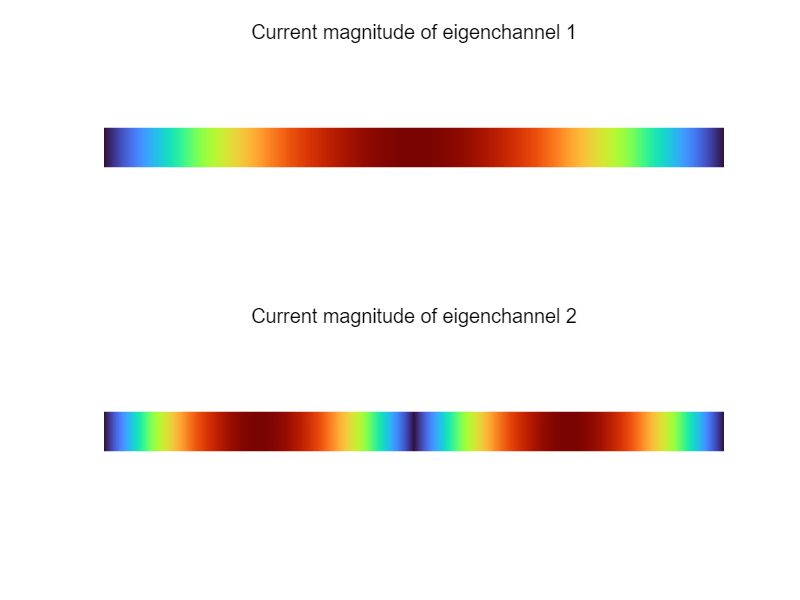

% =========================================================================
% Thin-Wire Antenna Characteristic Modes (Eigenchannels): Currents & Patterns
%
% This script implements characteristic-mode (eigenchannel) currents and
% radiation patterns of a thin-wire antenna. It demonstrates:
%   (1) Eigenchannel current distributions on the wire
%   (2) Mixed-channel current asymmetry due to superposition
%   (3) Mixed-channel far-field intensity and its inversion symmetry
%       using a cut-shell 3D visualization
%
% Copyright (c) 2026 Chenbo Shi, UESTC, China.
% =========================================================================

clear; close all; clc;

%% ----------------------------- Parameters ------------------------------
% Antenna / EM parameters (normalized)
lambda = 1;
k      = 2.005 * pi / lambda;   % slightly non-integer to avoid numerical edge cases
L      = lambda;
eta0   = 1;

% Eigenchannel current on the wire:
% u = pi*z/L, z in [0, L] => u in [0, pi]
In = @(n,u) sin(n .* u);

% Far-field amplitude of eigenchannels
Kappa = @(n) n * pi / L;
Nfac  = @(n,th) (k*eta0) ./ (2*pi*Kappa(n)) .* sin(th) ./ ...
    (1 - (k./Kappa(n)).^2 .* cos(th).^2);
Fo = @(n,th) Nfac(n,th) .* cos(k*L/2 .* cos(th));
Fe = @(n,th) 1i * Nfac(n,th) .* sin(k*L/2 .* cos(th));

%% ----------------------------- Plot grids ------------------------------
% Current sampling along the wire
Nt = 1000;
t  = linspace(0, pi, Nt).';     % column vector (u-grid)

% Wire geometry for visualization (colored patch)
i  = 1:Nt;
x  = [i; i; i+1; i+1] / 8;
y  = [0*i-2; 0*i+2; 0*i+2; 0*i-2] * 2;

%% ---------------------- Plot eigenchannel currents ---------------------
figure('Name','Eigenchannel Currents','Color','w');
colormap("turbo");

subplot(2,1,1);
I = In(1,t);
patch(x,y,abs(I),'edgecolor','none');
axis equal; axis off;
title('Current magnitude of eigenchannel 1');

subplot(2,1,2);
I = In(2,t);
patch(x,y,abs(I),'edgecolor','none');
axis equal; axis off;
title('Current magnitude of eigenchannel 2');

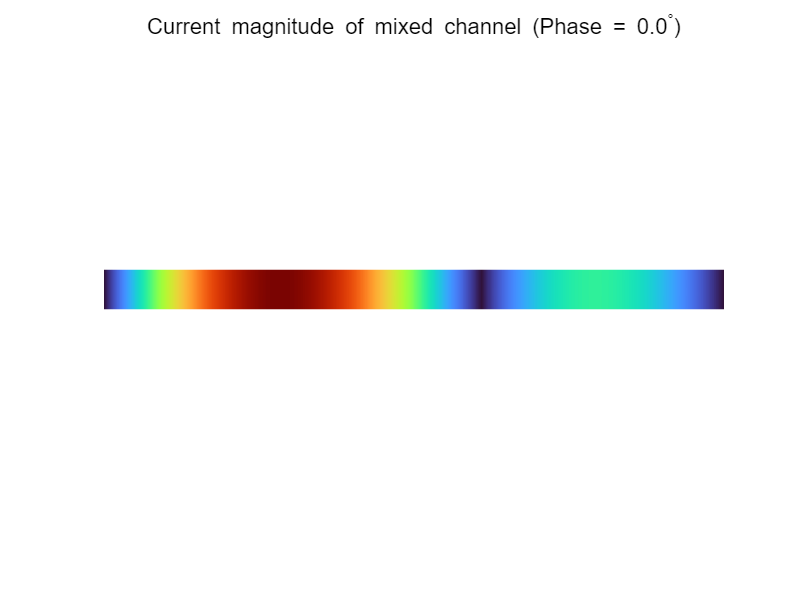


%% --------------------- Mixed-channel current (phase) --------------------
% You can freely change this phase (in degrees).
PhaseDeg = 0;

figure('Name','Mixed-Channel Current','Color','w');
colormap("turbo");
Imix = 0.67 * In(1,t) + exp(1i * deg2rad(PhaseDeg)) * In(2,t);
patch(x,y,abs(Imix),'edgecolor','none');
axis equal; axis off;
title(sprintf('Current magnitude of mixed channel (Phase = %.1f^\\circ)', PhaseDeg));

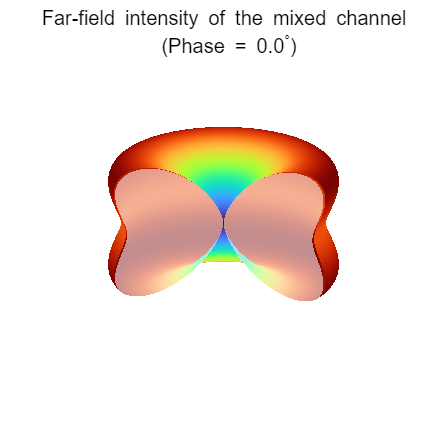


%% --------------------- Mixed-channel far-field pattern ------------------
% Keep the SAME mesh definition style as your original working version.
ndipt = 180; % sampling points

sita = meshgrid(eps:pi/ndipt:pi);        % theta grid (N x N)
fai  = meshgrid(0:2*pi/ndipt:2*pi)';     % phi grid   (N x N)  (transpose matches original)

% IMPORTANT:
% Use degrees consistently (PhaseDeg), convert to radians for exp(j*phase).
phaseRad = deg2rad(PhaseDeg);

% Mixed far-field magnitude (first two modes)
F = abs(0.67 * Fo(1, sita) + exp(1i * phaseRad) * Fe(2, sita));

% --- Normalization (robust spherical integration on this grid) ---
dth = pi/ndipt;
dph = 2*pi/ndipt;
dOmega = dth * dph;

D0 = sum( (F.^2) .* sin(sita), 'all' ) * dOmega;   % scalar
D  = 4*pi * (F.^2) / D0;

% ---- Create figure sized for publication ----
fig = figure('Name','Mixed-Channel Far-Field','Color','w');
set(fig, 'Units', 'Inches', 'Position', [1, 1, 3, 3]);

hAxes = axes('Parent', fig);
colormap(hAxes, "turbo");
axis(hAxes, 'equal'); axis(hAxes, 'off');
hold(hAxes, 'on');

% Adaptive axis limits (prevents empty plot due to clipping)
lim = max(D(:), [], 'omitnan');
if ~isfinite(lim) || lim <= 0
    lim = 1;
end
axis(hAxes, [-lim lim -lim lim -lim lim]);

%% -------------------------- Cut-shell rendering -------------------------
phi1 = deg2rad(200);
phi2 = deg2rad(330);
mask = (fai >= phi1) & (fai <= phi2);

% 1) Remove wedge by NaN "hole"
D_cut = D;
D_cut(mask) = NaN;

[xc,yc,zc] = sph2cart(fai, pi/2 - sita, D_cut);

% Keep your original coordinate mapping surf(x,z,y)
hSurf = surf(hAxes, xc, zc, yc, D_cut);
set(hSurf,'EdgeColor','none');
shading(hAxes, 'interp');

% 2) Add two semi-transparent slice faces at phi=phi1 and phi=phi2
% Avoid dependency on Mapping Toolbox's wrapToPi
wrapPi = @(x) atan2(sin(x), cos(x)); % wrap to [-pi, pi]

phi_vec = fai(:,1);
[~, i1] = min(abs( wrapPi(phi_vec - phi1) ));
[~, i2] = min(abs( wrapPi(phi_vec - phi2) ));

for ii = [i1 i2]
    phi_line   = fai(ii,:);
    theta_line = sita(ii,:);
    r_line     = D(ii,:);            % use uncut boundary values

    [xb,yb,zb] = sph2cart(phi_line, pi/2 - theta_line, r_line);

    % Close the fan: origin -> boundary curve -> origin
    Xp = [0, xb, 0];
    Yp = [0, zb, 0];  % second coord is Z (since surf(x,z,y))
    Zp = [0, yb, 0];  % third coord is Y

    patch(hAxes, Xp, Yp, Zp, 'w', ...
        'FaceAlpha', 0.55, ...
        'EdgeColor', 'none');
end

uistack(findobj(hAxes,'Type','patch'), 'top');

% 3) View and dynamic title
view(hAxes, 0, -70);
title(hAxes, sprintf('Far-field intensity of the mixed channel\n (Phase = %.1f^\\circ)', PhaseDeg));

hold(hAxes, 'off');